# Метод *k*-средних

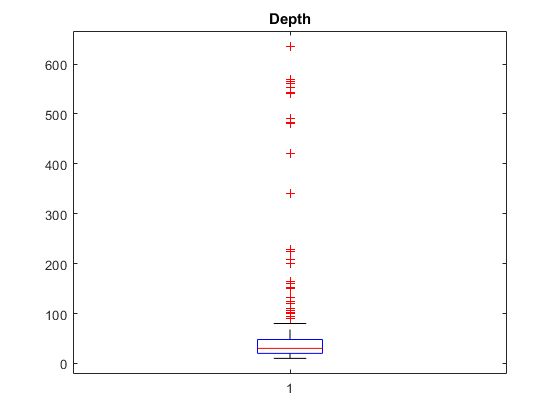

load database.mat

%добавляем комментарий
X=[database(2:end, 6), database(2:end, 9)];
X=rmmissing(X);


boxplot(X.Depth);
title('Depth');

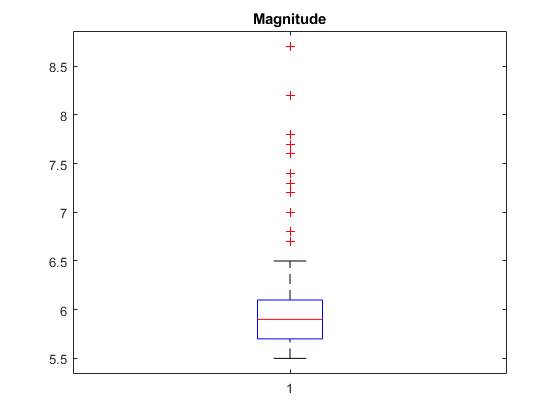

boxplot(X.Magnitude);
title('Magnitude');

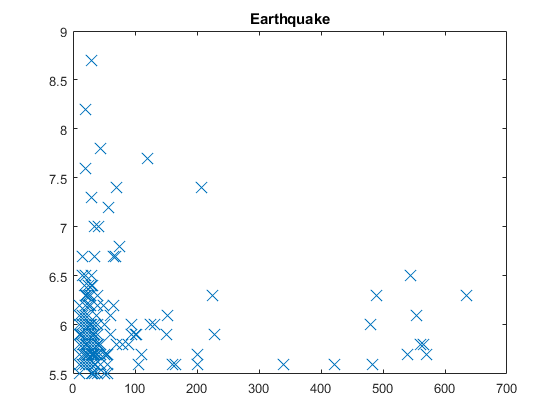

figure;
plot(X{:,'Depth'},X{:,'Magnitude'},'x','MarkerSize',12);
title 'Earthquake';


opts = statset('Display','final');
x=X{:,1:2}

x =   131.6000    6.0000
   80.0000    5.8000
   20.0000    6.2000
   15.0000    5.8000
   15.0000    5.8000
   35.0000    6.7000
   20.0000    5.9000
   35.0000    6.0000
   95.0000    6.0000
  565.0000    5.8000



[idx,C] = kmeans(x,2,'Distance','cityblock', 'Replicates',5,'Options',opts);

Replicate 1, 1 iterations, total sum of distances = 4709.3.
Replicate 2, 6 iterations, total sum of distances = 4709.3.
Replicate 3, 6 iterations, total sum of distances = 4709.3.
Replicate 4, 2 iterations, total sum of distances = 4709.3.
Replicate 5, 1 iterations, total sum of distances = 4709.3.
Best total sum of distances = 4709.3


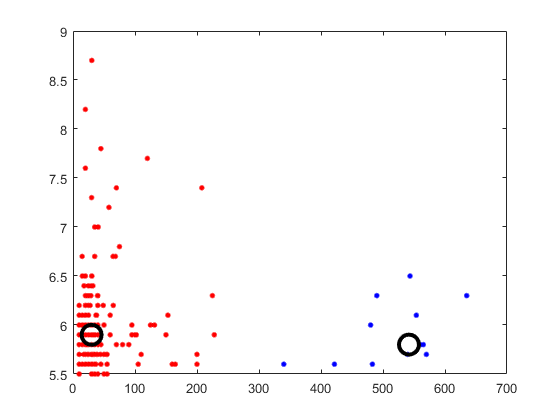


figure;
plot(x(idx==1,1),x(idx==1,2),'r.','MarkerSize',12)
hold on
plot(x(idx==2,1),x(idx==2,2),'b.','MarkerSize',12)
plot(C(:,1),C(:,2),'ko','MarkerSize',15,'LineWidth',3) 

hold off

# Метод нечёткой кластеризации C-средних

clear
clc
load database.mat

fcmdata=[database(2:end, 6), database(2:end, 9)];
fcmdata=rmmissing(fcmdata);


opt = [NaN 300 NaN NaN];

[centers,U] = fcm(fcmdata,2, opt);

Undefined function 'fcm' for input arguments of type 'table'.

maxU = max(U);
index1 = find(U(1,:) == maxU);
index2 = find(U(2,:) == maxU);
plot(fcmdata(index1,1),fcmdata(index1,2),'ob')
hold on
plot(fcmdata(index2,1),fcmdata(index2,2),'or')
plot(centers(1,1),centers(1,2),'xb','MarkerSize',15,'LineWidth',3)
plot(centers(2,1),centers(2,2),'xr','MarkerSize',15,'LineWidth',3)
hold off

C1_leptin = [fcmdata(:,1)'; U(1,:)];
C1_leptin = sortrows(C1_leptin');
C2_leptin = [fcmdata(:,1)'; U(2,:)];
C2_leptin = sortrows(C2_leptin');

plot(C1_leptin)
plot(C2_leptin)

C1_leptin_y=(C1_leptin(:,2));
C1_leptin_x=(1:length(C1_leptin_y))';
C2_leptin_y=(C2_leptin(:,2));
C2_leptin_x=(1:length(C2_leptin_y))';

% cftool(x,y)

f=fit(C1_leptin_x,C1_leptin_y,'poly5')
plot(f,C1_leptin_x,C1_leptin_y)

f=fit(C2_leptin_x,C2_leptin_y,'poly5')
plot(f,C2_leptin_x,C2_leptin_y)


